## Task-01

clc
clear
load chestVolume.mat
whos

  Name        Size                     Bytes  Class    Attributes

  V         512x512x318            166723584  int16              



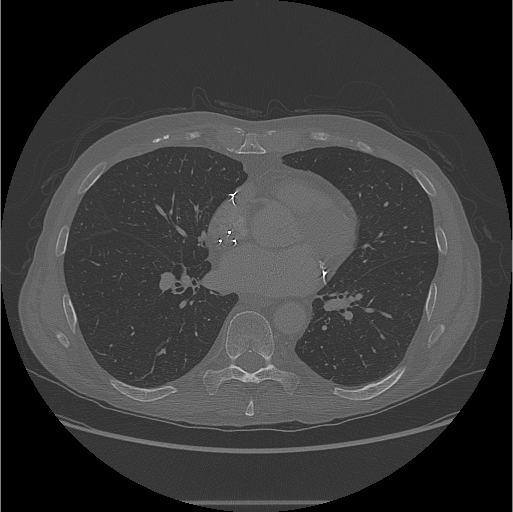

XY=squeeze(V(:,:,160));
imshow(XY,[],'Border','tight')

level=thresh_tool(uint16(XY),gray)

level = 674.1046

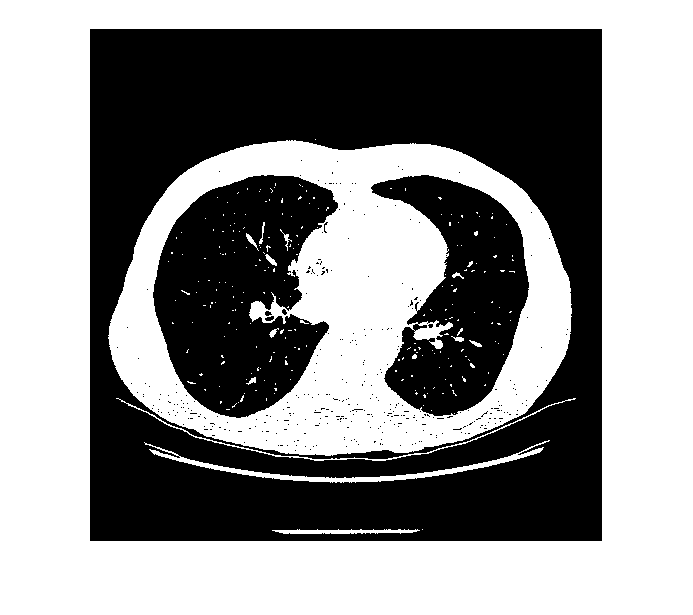

BW=XY>level;
imshow(BW,[])

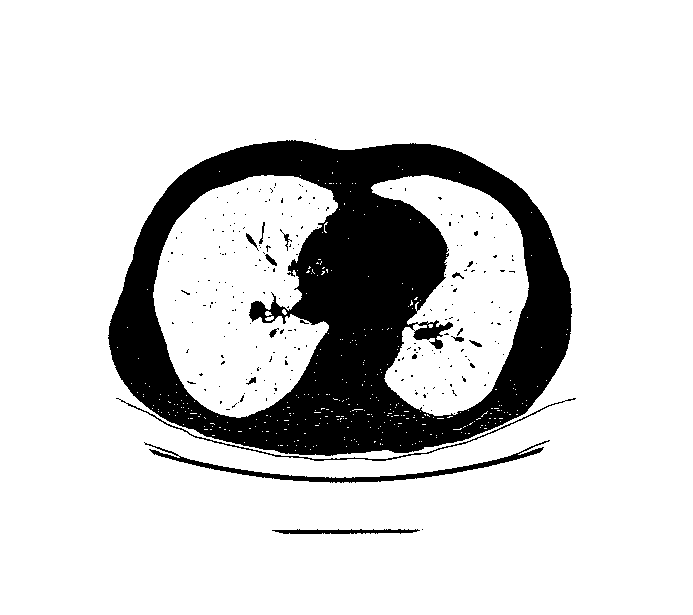

BW=imcomplement(BW);
imshow(BW,[])

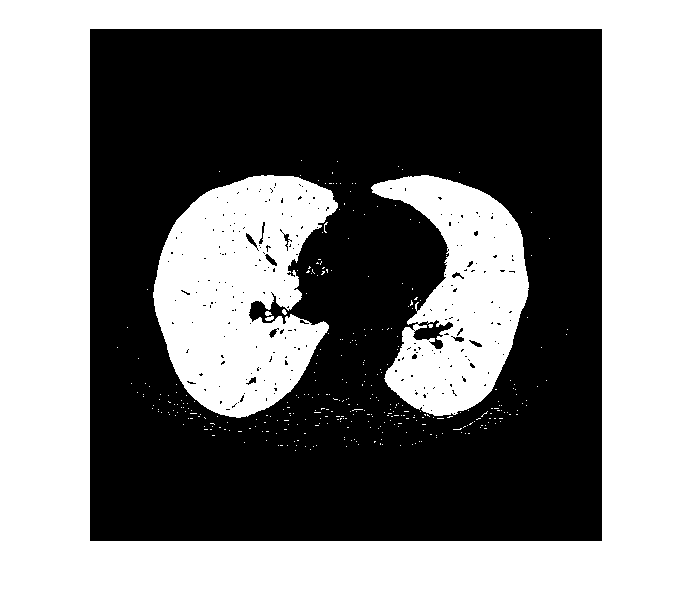

BW=imclearborder(BW);
imshow(BW,[])

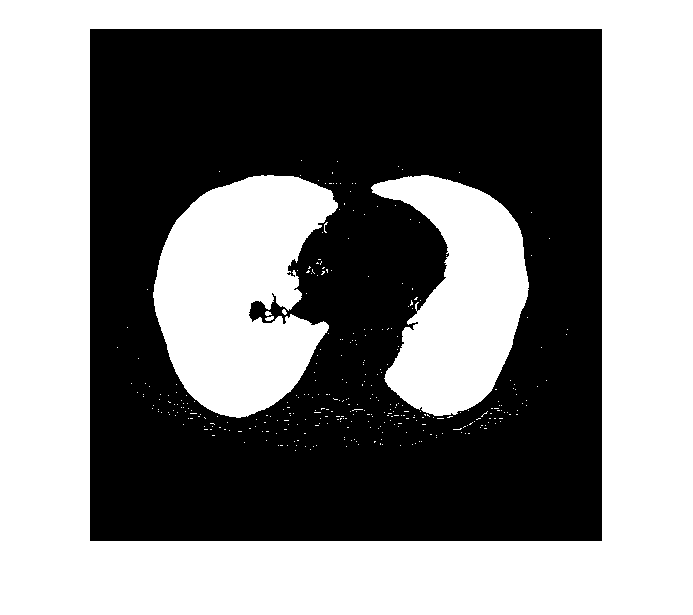

BW=imfill(BW,'holes');
imshow(BW,[])

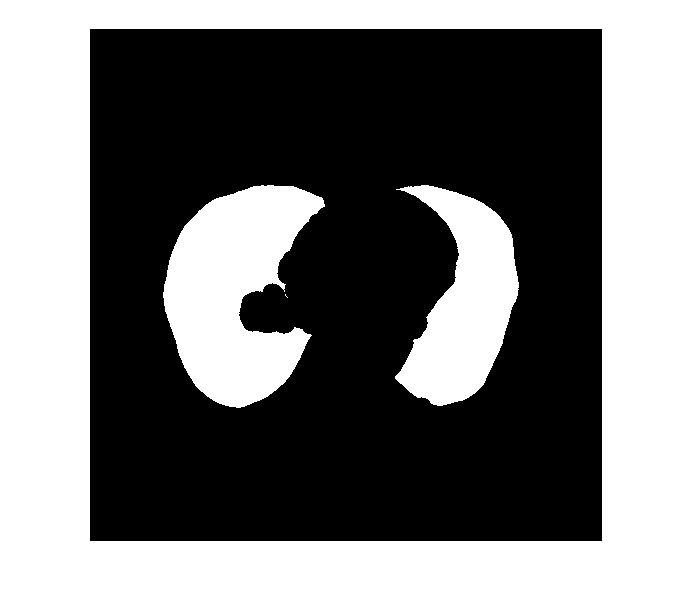

radius=10;
decomposition=0;
se=strel('disk',radius,decomposition);
BW=imerode(BW,se);
imshow(BW,[])

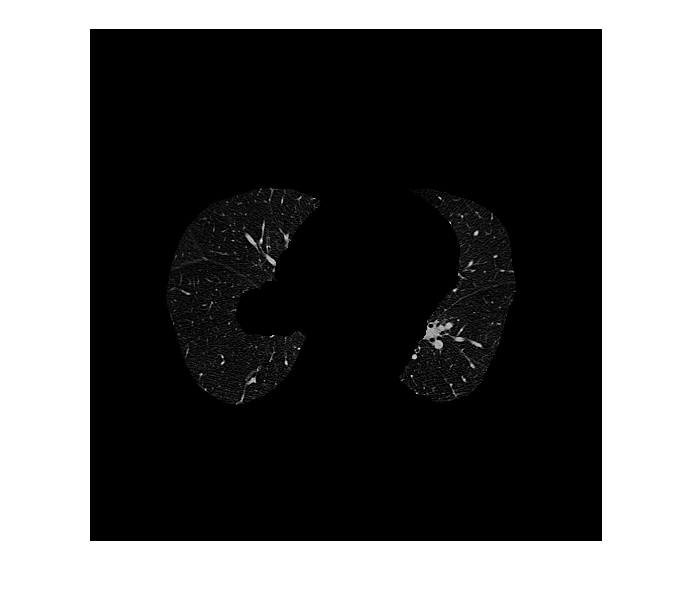

maskedImageXY=XY;
maskedImageXY(~BW)=0;
imshow(maskedImageXY,[])

# Task-2

clc
clear
close
load chestVolume.mat
whos

  Name        Size                     Bytes  Class    Attributes

  V         512x512x318            166723584  int16              



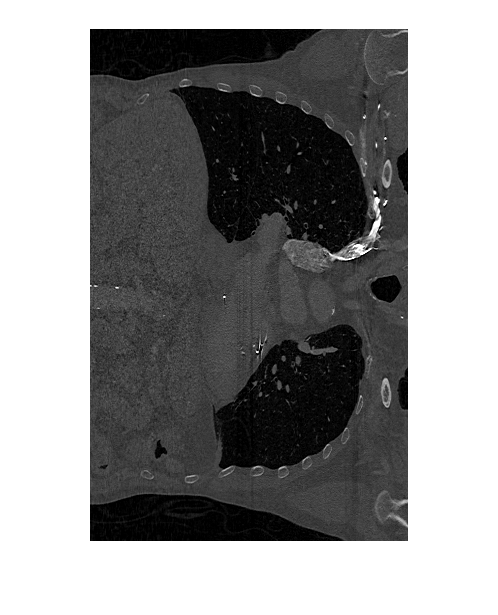

V=im2single(V);
XZ=squeeze(V(256,:,:));
imshow(XZ,[])

imageSegmenter(XZ)

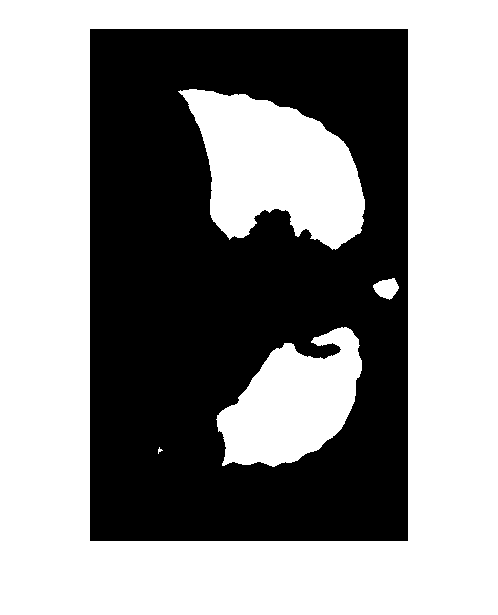

imshow(BW,[])

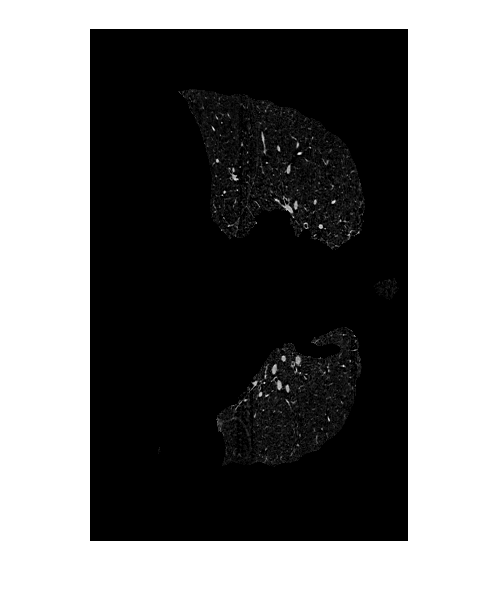

imshow(maskedImage)